16.13

close all
clc
clear

mot.k = 5.2;
mot.T = 0.03;
tau = 0.42;

s = tf('s');
P = mot.k / (s * (mot.T * s + 1));
C = (tau * s + 1) / s;

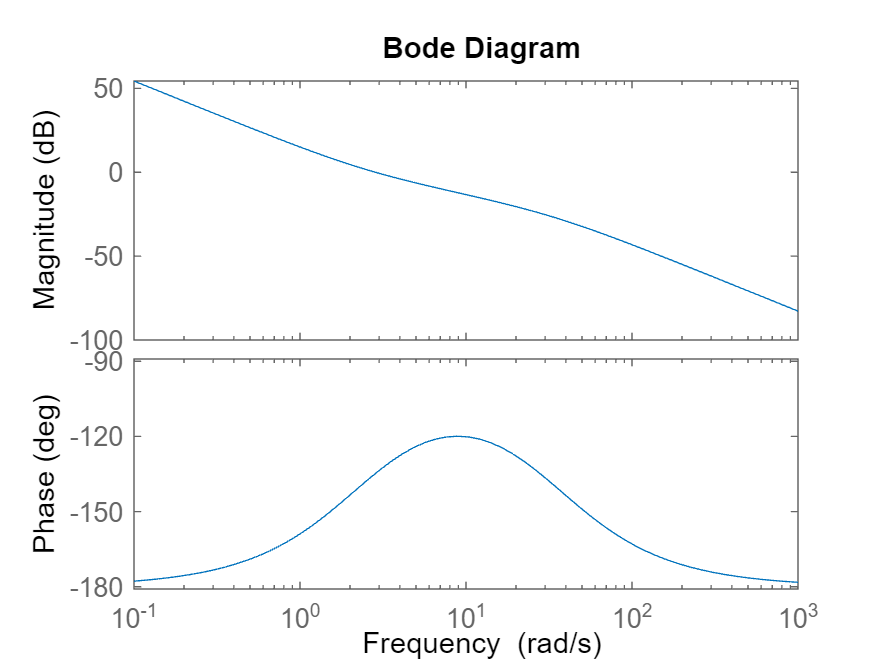

L = minreal(P * C, 1e-6);
close all
figure(1)
bode(L)

[~, phim, ~, wgc] = margin(L)

phim = 45.1532

wgc = 2.8398

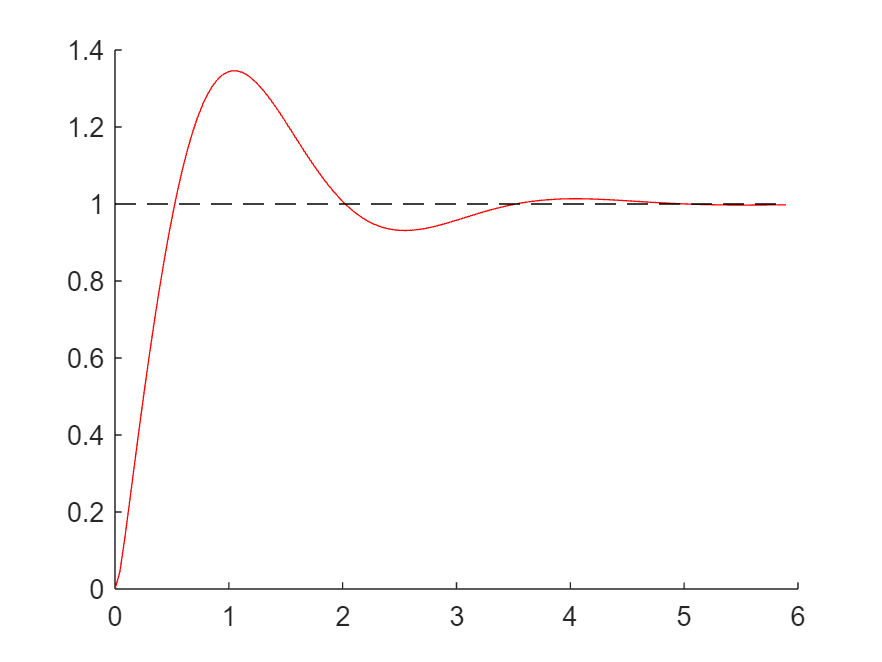

T = minreal(feedback(L, 1), 1e-6);
[y, t] = step(T);
close all
figure(2)
hold on
plot(t, y, "r")
plot([t(1), t(end)], [1, 1], "k--")

stepinfo(T, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.3896
    TransientTime: 2.9108
     SettlingTime: 2.9108
      SettlingMin: 0.9164
      SettlingMax: 1.3459
        Overshoot: 34.5867
       Undershoot: 0
             Peak: 1.3459
         PeakTime: 1.0676


Il guadagno è pari all'inverso del modulo di L in jwm con wm pulsazione per cui si ha fase massima.

w = logspace(0, 2, 600);
[ms, ps] = bode(L, w);
ms = squeeze(ms);
ps = squeeze(ps);
[pham, imax] = max(ps);
K = 1 / abs(ms(imax))

K = 4.0624

phi = pham + 180

phi = 60.0734

wgcm = ps(imax)

wgcm = -119.9266

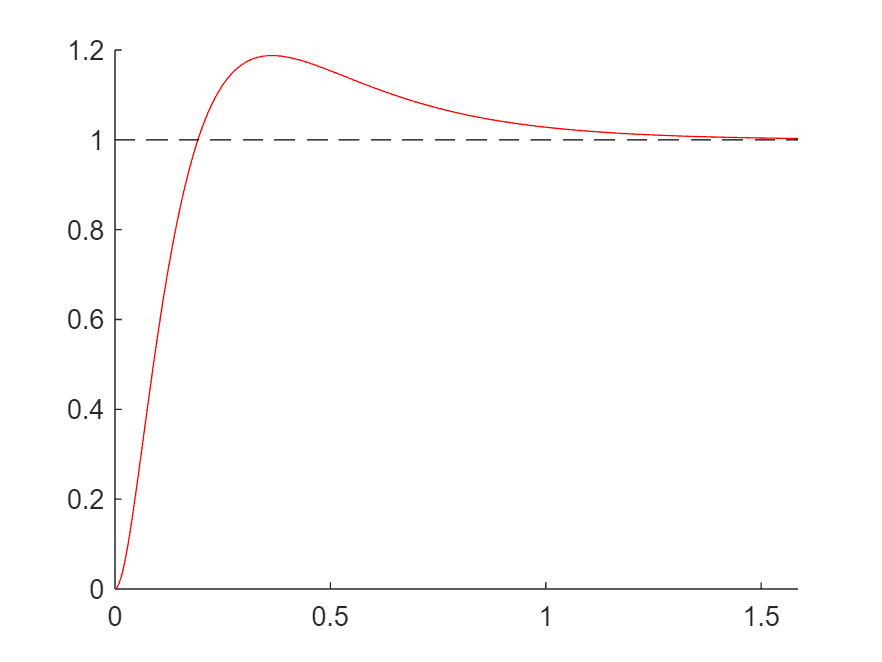

T2 = minreal(feedback(L * K, 1), 1e-6);
[y2, t2] = step(T2);
close all
figure(3)
hold on
plot(t2, y2, "r")
plot([t2(1), t2(end)], [1, 1], "k--")

stepinfo(T2, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.1331
    TransientTime: 0.8457
     SettlingTime: 0.8457
      SettlingMin: 0.9057
      SettlingMax: 1.1876
        Overshoot: 18.7587
       Undershoot: 0
             Peak: 1.1876
         PeakTime: 0.3653


16.34